% clear variables in workspace and close all figures
clearvars; close all;

% reading the data
% data = readtimetable('SJEHourlyOldData.xlsx');
% data = readtimetable('SaintJohnEnergy.xlsx');
data = readtimetable('OntarioIESO.xlsx');

% creating the effective temperature
temp_f = data.Temperature * (9/5) + 32;    % T(°F) = T(°C) × 9/5 + 32
T_eff = Effective_Temp(temp_f, data.Humidity, data.WindSpeed);

data  = addvars(data, T_eff, 'NewVariableNames', 'EffectiveTemperature');

% Normalizing the variables

% y = (x - min) / (max - min)
tmp = timetable2table(data);
maxdp = max(table2array(tmp(:, 2:end)));    % takes the max and min of each variable in the dataset
mindp = min(table2array(tmp(:, 2:end)));
tmp.DateTime = [];
normalize = (table2array(tmp) - mindp) ./ (maxdp - mindp);

% creating the normalized dataset
ndata = data;
ndata.DemandMW = normalize(:, 1);
ndata.Temperature = normalize(:, 2);
% ndata.Temperature = normalize(:, 7);    % uses the effective temperature instead of normal one
ndata.Humidity = normalize(:, 3);
ndata.Dewpoint = normalize(:, 4);
ndata.WindDirection = normalize(:, 5);
ndata.WindSpeed = normalize(:, 6);

% ndata.EffectiveTemperature = [];


clearvars -except data ndata mindp maxdp

### Inputs and Targets Creation

There are 79 inputs for both forecasters consisting of:

- 24 hourly load from the previous day

- 24 hourly weather data from the previous day

- 24 hourly weather parameters for the coming day

- 7 day type indicator for each day of the week; refering to the coming day.

The Base Load Forecaster (BLF) predicts the 24 hrs output for the next day.

The Change in the Load Forecaster (CLF) predicts the change in the hourly load between yesterday and today. To get the CLF load forecast, the output of the CLF module are added to the load of yesterday.

% Inputs Creation

p=buffer(ndata.DemandMW,24);
t=buffer(ndata.Temperature,24);
d = buffer(weekday(ndata.DateTime),24);
d = d(1, :);

% creates a weekday string for the next day
N = length(d)-1;
dcode=zeros(7,N);
for i=1:size(dcode,2)
    
    dcode(d(i+1),i)=1;
    
end

% creates the final inputs
inputs = [p(:,1:end-1); t(:,1:end-1);t(:,2:end);dcode];

% Target variables
blf_outputs = p(:,2:end);
clf_outputs = p(:, 2:end) - p(:, 1:end-1); %change in the load
% clf_outputs = p(:, 1:end-1) + clf_changes;
time_outputs = ndata.DateTime(25:end);

clearvars -except data ndata mindp maxdp clf_outputs blf_outputs inputs time_outputs p

## Training the Forecasters

### Base Load Forecaster training

/*What ever  timeframe you are forecasting can be removed from the training/validation dataset

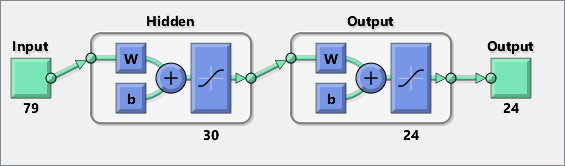

clear net

x = inputs;
t = blf_outputs;

% trainFcn = 'trainlm';  % Levenberg-Marquardt backpropagation. Was quite slow in training
trainFcn = 'trainrp';   % Resilient backpropagation


% Create a Fitting Network
hiddenLayerSize = 30;
% net = feedforwardnet(hiddenLayerSize,trainFcn);
net = fitnet(hiddenLayerSize,trainFcn);

% logsig = 1 / 1 + e^(-z) ; tansig = 2/(1+exp(-2*n))-1;
% using tansig gave better predictions.
% Increasing the no. of neurons didn't make logsig prediction better.
net.layers{1}.transferFcn = 'tansig'; % converts the output layer's function to sigmoid
net.layers{2}.transferFcn = 'tansig'; % converts the output layer's function to sigmoid


% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;
% net.divideFcn = 'divideblock';


% Train the Network
[net,trBLF] = train(net,x,t);

% % Getting the datasets used in training, validation, and testing
% train_set = blf_outputs(:,trBLF.trainInd);
% val_set = blf_outputs(:,trBLF.valInd);
% test_set = blf_outputs(:,trBLF.testInd);

% Test the Network
% y = net(x);
% e = gsubtract(t,y);
% performance = perform(net,t,y)

% View the Network
newView(net)

blf_net = net;

### Change in the Load Forecaster Training

/*What ever  timeframe you are forecasting can be removed from the training/validation dataset

clear net

x = inputs;
t = clf_outputs;

% trainFcn = 'trainlm';  % Levenberg-Marquardt backpropagation. Was quite slow in training
trainFcn = 'trainrp';   % Resilient backpropagation


% Create a Fitting Network
hiddenLayerSize = 30;
% net = feedforwardnet(hiddenLayerSize,trainFcn);
net = fitnet(hiddenLayerSize,trainFcn);

% logsig = 1 / 1 + e^(-z) ; tansig = 2/(1+exp(-2*n))-1;
% using tansig gave better predictions.
% Increasing the no. of neurons didn't make logsig prediction better.
net.layers{1}.transferFcn = 'tansig'; % converts the output layer's function to sigmoid
net.layers{2}.transferFcn = 'tansig'; % converts the output layer's function to sigmoid


% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;
% net.divideFcn = 'divideblock';

% Train the Network
[net,trCLF] = train(net,x,t);

% % Getting the datasets used in training, validation, and testing
% train_set = clf_outputs(:,trCLF.trainInd);
% val_set = clf_outputs(:,trCLF.valInd);
% test_set = clf_outputs(:,trCLF.testInd);

% Test the Network
% y = net(x);
% e = gsubtract(t,y);
% performance = perform(net,t,y)

% View the Network
newView(net)

clf_net = net;

## Predict the whole dataset (train +validation + test sets)

### Generate BLF forecasts

% generate the forecasts
yBLF = blf_net(inputs);

% denormalize predicted values
yBLF = yBLF * (maxdp(1) - mindp(1)) + mindp(1);

% these are the actual, denormalized load demand values 
actuals = blf_outputs * (maxdp(1) - mindp(1)) + mindp(1);

### Generate CLF forecasts

% generate the forecasts
yCLF = clf_net(inputs) + p(:,1:end-1);

% denormalize predicted values
yCLF = yCLF * (maxdp(1) - mindp(1)) + mindp(1);


% separate train, test and validation sets
trn_BLF = yBLF .* trBLF.trainMask{1};
tst_BLF = yBLF .* trBLF.testMask{1};
val_BLF = yBLF .* trBLF.valMask{1};

trn_CLF = yCLF .* trCLF.trainMask{1};
tst_CLF = yCLF .* trCLF.testMask{1};
val_CLF = yCLF .* trCLF.valMask{1};

### Calculate errors


%BLF errors
eBLF = actuals - yBLF;

blf_APEs = abs(eBLF) ./ abs(yBLF);

trn_BLF_MAPE = 100 * mean(mean(blf_APEs(:,trBLF.trainInd)));
tst_BLF_MAPE = 100 * mean(mean(blf_APEs(:,trBLF.testInd)));
val_BLF_MAPE = 100 * mean(mean(blf_APEs(:,trBLF.valInd)));

% CLF errors
eCLF = actuals - yCLF;
clf_APEs = abs(eCLF) ./ abs(yCLF);

trn_CLF_MAPE = 100 * mean(mean(clf_APEs(:,trCLF.trainInd)));
tst_CLF_MAPE = 100 * mean(mean(clf_APEs(:,trCLF.testInd)));
val_CLF_MAPE = 100 * mean(mean(clf_APEs(:,trCLF.valInd)));

## Plot actual values and forecasts for BLF

figure;

sp(1) = subplot(211);

% plot actual values
plot(time_outputs, actuals(:)/1000, 'DisplayName','Actual Values')
title('BLF forecasts')
ylabel('Load demand (MW)')
grid on; 
hold on;


% plot training set
DisplayName = num2str(trn_BLF_MAPE,'TrainSet (MAPE = %.2f%%)');
plot(time_outputs,trn_BLF(:)/1000, 'DisplayName', DisplayName)

% plot test set
DisplayName = num2str(tst_BLF_MAPE, 'TestSet (MAPE = %.2f%%)');
plot(time_outputs,tst_BLF(:)/1000, 'DisplayName', DisplayName)

% plot validation set
DisplayName = num2str(val_BLF_MAPE, 'ValidationSet (MAPE = %.2f%%)');
plot(time_outputs,val_BLF(:)/1000, 'DisplayName', DisplayName)

legend('show')

## Plot actual values and CLF forecasts 

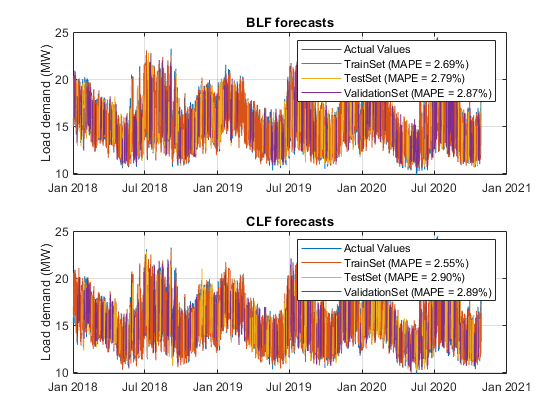

sp(2) = subplot(212);

% plot actual values
plot(time_outputs, actuals(:)/1000, 'DisplayName','Actual Values')
title('CLF forecasts')
ylabel('Load demand (MW)')
grid on; 
hold on;


% plot training set
DisplayName = num2str(trn_CLF_MAPE,'TrainSet (MAPE = %.2f%%)');
plot(time_outputs,trn_CLF(:)/1000, 'DisplayName', DisplayName)

% plot test set
DisplayName = num2str(tst_CLF_MAPE, 'TestSet (MAPE = %.2f%%)');
plot(time_outputs,tst_CLF(:)/1000, 'DisplayName', DisplayName)

% plot validation set
DisplayName = num2str(val_CLF_MAPE, 'ValidationSet (MAPE = %.2f%%)');
plot(time_outputs,val_CLF(:)/1000, 'DisplayName', DisplayName)

legend('show')
linkaxes(sp)

## Forecasting a Portion of The Dataset

clearvars -except data ndata mindp maxdp clf_outputs blf_outputs inputs blf_net clf_net

### BLF - 24H ahead predictions (Day by Day)

We forecast one day at a time using the actual values of the previous day as inputs.

clear by bx bt

index = 35; % number of days to forecast
bt = blf_outputs(:, end-index+1 : end); %The target variable for the desired days
lend = index;

% predicts day by day using the intial inputs and the generated inputs
% that uses the actual value of the previous day.
for i=1:lend
    bx(:, i) = inputs(:, end-index+1);  % gets the original input of the day we are about to predict
    if i > 1
        bx(1:24, i) = bt(1:24, i-1); % actual value from previous day
    end
    
    by(:, i) = blf_net(bx(:, i)); % The forecasts
    index = index - 1;  % reduces index so we can move forward to forecasts the next day
end

time = data.DateTime(end - lend*24 +1 : end); % gets the timeline for the prediction

% by = reshape(by, [], 1); % merges all columns to one
% bt = reshape(bt, [], 1);

### CLF - 24H ahead predictions (Day by Day)

The BLF and CLF always have the same input.

We forecast one day at a time using the actual values of the previous day as inputs. Since it's a 24h ahead prediction, the actual load of yesterday can be added to the clf forecast to get the final clf forecast. If's a larger horizon  > 24h or 1 day; the clf final forecast of yesterday can be added instead.

clear cy cx ct

index = lend;   % number of days to forecast
% ct = clf_outputs(:, end-index+1 : end); %The target variable for the desired days

prev_day_load = ndata.DemandMW(time - days(1));  % takes the actual demand of yesterday
prev_day_load = buffer(prev_day_load,24);   % the final clf forecast

% predicts day by day using the intial inputs and the generated inputs
% that uses the actual value of the previous day.
for i=1:lend
    cx(:, i) = inputs(:, end-index+1);   % gets the original input of the day we are about to predict
 
    if i > 1
        cx(1:24, i) = bt(1:24, i-1); % actual value from previous day
    end
    
    cy(:, i) = clf_net(cx(:, i)) + prev_day_load(:,i); % The final forecasts
    index = index - 1;  % reduces index so we can move forward to forecasts the next day
end

% cy = reshape(cy, [], 1); % merges all columns to one
% ct = reshape(ct, [], 1);

### RLS Combiner

% Inputs
blfy = by;
clfy = cy;

% Desired value
desired = bt;

days = size(blfy);
days = days(1, 2);  % gets the number of days we are forecasting

[rlsy, weight] = RLS_Combiner(blfy, clfy, desired, days); % calls the rls combiner

## Visualizing the results

% clearvars -except data ndata mindp maxdp clf_outputs blf_outputs inputs blf_net clf_net blfy clfy desired rlsy time

blfy = reshape(blfy, [], 1); % merges all columns to one
clfy = reshape(clfy, [], 1); 
rlsy = reshape(rlsy, [], 1); 
desired = reshape(desired, [], 1);

% Denormalization
blfy = blfy*(maxdp(1) - mindp(1)) + mindp(1);   % gets back the original data using the min and max Demand
clfy = clfy*(maxdp(1) - mindp(1)) + mindp(1);
rlsy = rlsy*(maxdp(1) - mindp(1)) + mindp(1);
desired = desired*(maxdp(1) - mindp(1)) + mindp(1);

% MAPE calculations
blf_MAPE = mean(abs(desired'-blfy')/desired')*100;  % calculate mape after denormalization could make the mape smaller due to high denominator values
clf_MAPE = mean(abs(desired'-clfy')/desired')*100;
rls_MAPE = mean(abs(desired'-rlsy')/desired')*100;

% calculating the errors
blfe = gsubtract(desired, blfy);
clfe = gsubtract(desired, clfy);
rlse = gsubtract(desired, rlsy);

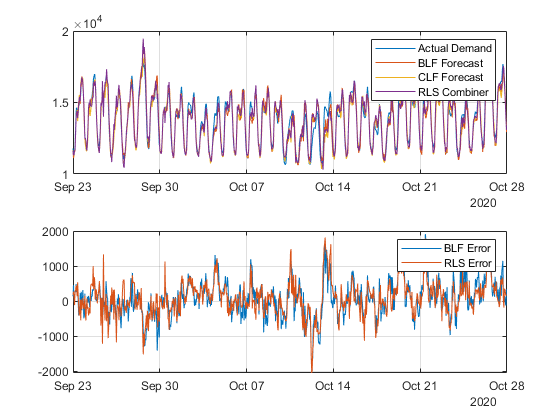

% Plots
figure
subplot(2,1,1)
plot(time, desired, time, blfy, time, clfy, time, rlsy)
legend('Actual Demand', 'BLF Forecast', 'CLF Forecast', 'RLS Combiner')
grid

subplot(2,1,2)
plot(time, blfe, time, rlse)
legend('BLF Error', 'RLS Error')
% plot(time, blfe, time, clfe, time, rlse)
% legend('BLF Error', 'CLF Error', 'RLS Error')
grid